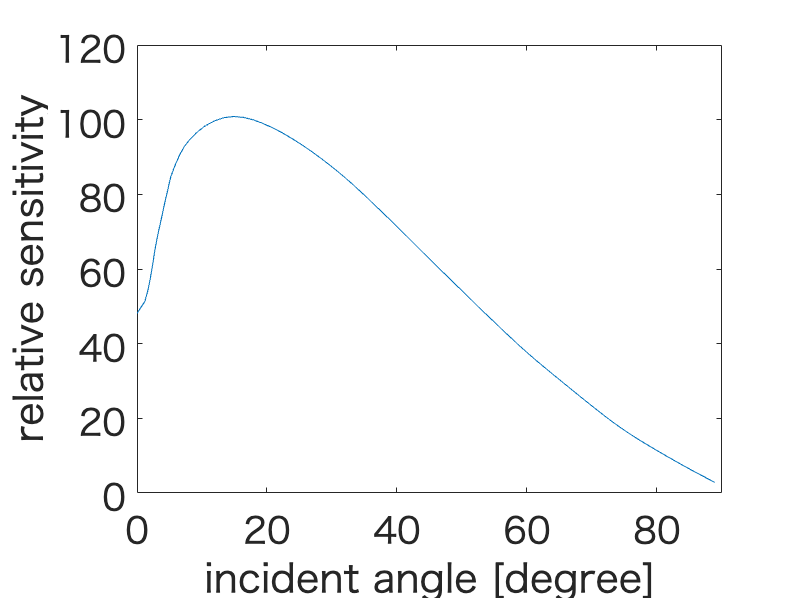

n = 80; %number of grid
Z = 24.4; %distance between the MCP and the pinhole [mm]
X = 17; %diameter of the view area
Y = X;
D = zeros(n);
d_x = X/n; %distance between grids
d_y = Y/n;
b_angle = 8*pi/180; %bias angle (8 degrees)
b_vec = [sin(b_angle),0,cos(b_angle)]; %vector of the bias angle
I = eye(3); %identity matrix
n_vec = [0,0,1]; %norm vector of the MCP surface
n_mat = [0 -1 0; 1 0 0; 0 0 0]; %representation matrix for vector product
theta = pi*3/4; %angle of the MCP-in pin (rightward is 0 and counterclockwise is positive)

%rotate the bias vector (b_vec) when theta is not equal to zero
rot_vec = theta * n_vec;
rot_mat = rotvec2mat3d(rot_vec);
b_vec = transpose(rot_mat*transpose(b_vec));

%calculate the incident angle of soft X-ray aginst each grid 
for i = 1:n
    for j = 1:n
        x = d_x*(i-1);
        y = d_y*(j-1);
        p_vec = [(X/2)-x,(Y/2)-y,Z];
        D(j,i) = acos(dot(p_vec,b_vec)/(norm(p_vec)*norm(b_vec)))/(2*pi)*360;
    end
end

D1 = reshape(D,1,[]);
D1 = unique(D1);
filename = '/Users/shinjirotakeda/Library/CloudStorage/OneDrive-TheUniversityofTokyo/研究資料/機器マニュアル/MCP/Default Dataset.csv';
Data = readmatrix(filename);
Angle = Data(:,1);
Sensitivity = Data(:,2);
figure;plot(Angle,Sensitivity);
xlim([0,90]);
xlabel('incident angle [degree]');
ylabel('relative sensitivity');
ax=gca;ax.FontSize=18;

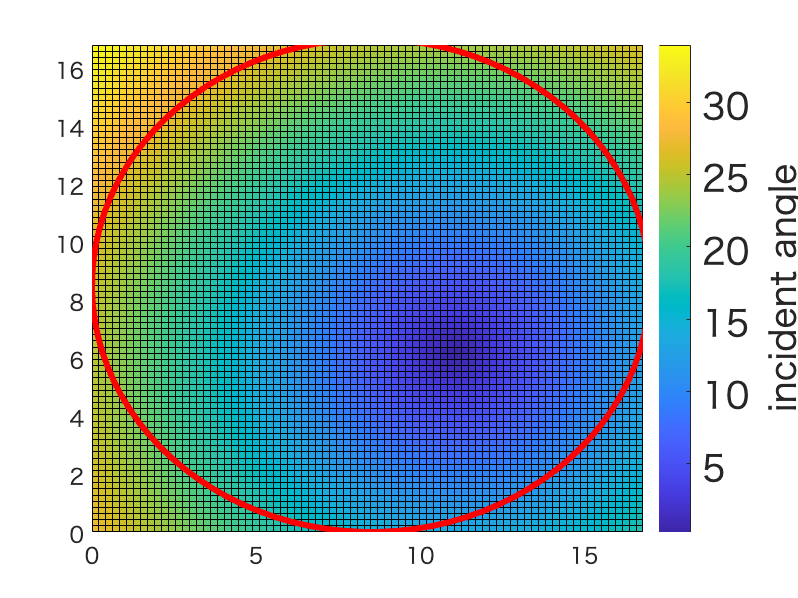

RS = spline(Angle,Sensitivity,D1);
% figure;plot(D1,RS);
SD = zeros(n);
for i = 1:n
    for j = 1:n
        SD(i,j) = RS(D1==D(i,j));
    end
end


[DX,DY] = meshgrid(0:d_x:X-d_x,0:d_y:Y-d_y);

% cx = X/2-0.25; 
% cy = Y/2-0.25;
cx = X/2; 
cy = Y/2;
r = X/2;

f1 = figure;
pcolor(DX,DY,D) %plot the incident angle
c=colorbar;c.Label.String=('incident angle');c.FontSize=18;
hold on
t = linspace(0,2*pi,100);
plot(r*sin(t)+cx,r*cos(t)+cy,'Color','r','LineWidth',3) %plot the MCP area
hold off

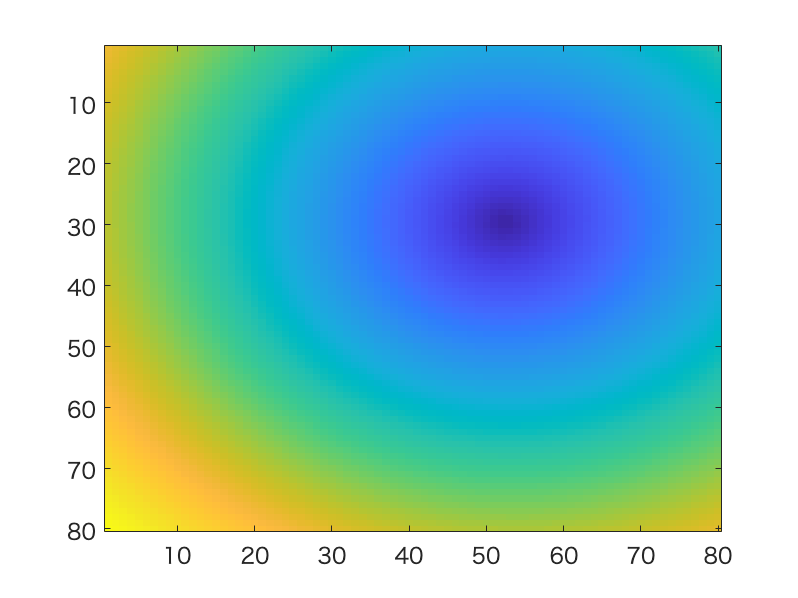


% figure;imagesc(D);

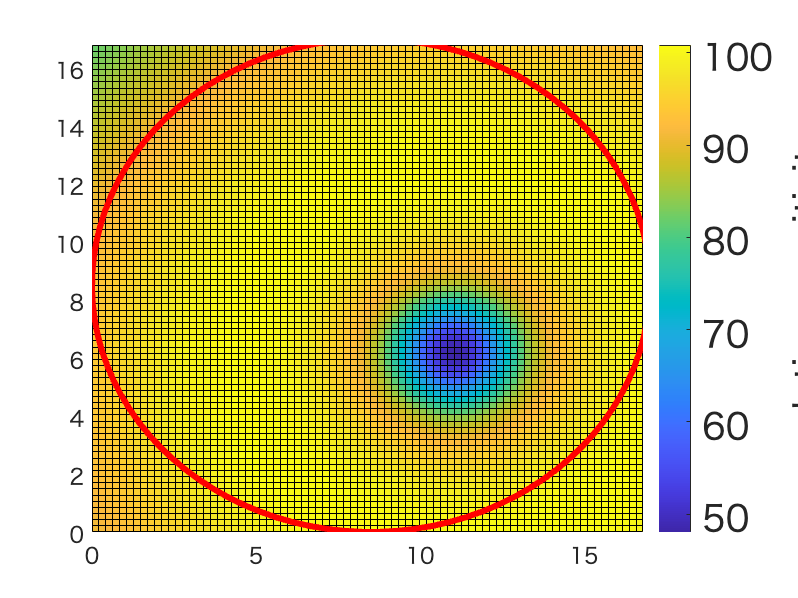


f2 = figure;
pcolor(DX,DY,SD)
c=colorbar;c.Label.String=('relative sensitivity');c.FontSize=18;
hold on
t = linspace(0,2*pi,100);
plot(r*sin(t)+cx,r*cos(t)+cy,'Color','r','LineWidth',3) %plot the MCP area
hold off

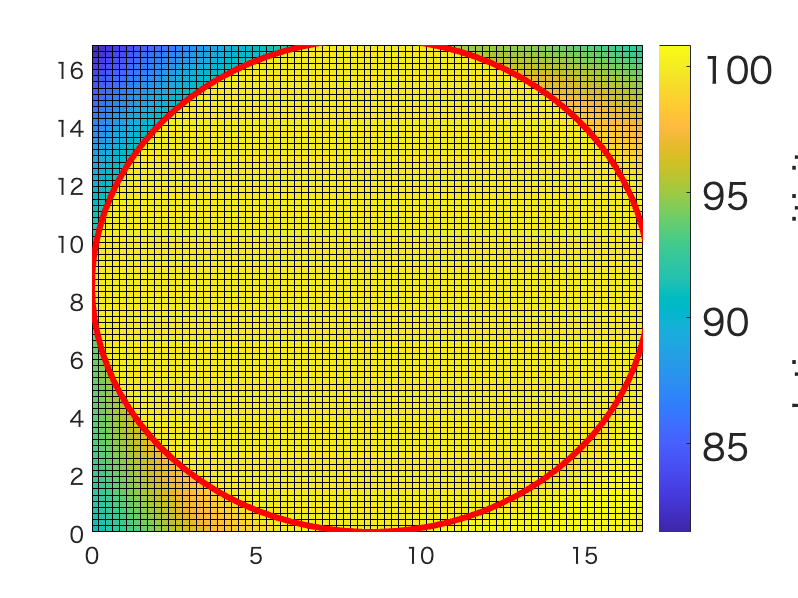


L = 40;
R = zeros(2*L);
for i = 1:2*L
    for j = 1:2*L
        R(i,j) = sqrt((L-i+0.5)^2+(j-L-0.5)^2);
    end
end
% figure;imagesc(R)
k = find(R<L);

cf = 100./SD; 
cf = cf(k);
SD(k) = SD(k).*cf;

f3 = figure;
pcolor(DX,DY,SD)
c=colorbar;c.Label.String=('relative sensitivity');c.FontSize=18;
hold on
t = linspace(0,2*pi,100);
plot(r*sin(t)+cx,r*cos(t)+cy,'Color','r','LineWidth',3) %plot the MCP area
hold off